%Week 2 worksheet
%question 1
syms y(x)

%declaring cofficients (change coefficients for question one here)
a = 1.23456

a =    1.234560000000000


b = 3.45678

b =    3.456780000000000


c = -5.6789

c =   -5.678900000000000



%declaring function
y(x) = a*x^2+b*x+c

$$y(x) = \frac{3858\,x^{2}}{3125}+\frac{1945994139987723\,x}{562949953421312}-\frac{56789}{10000}$$

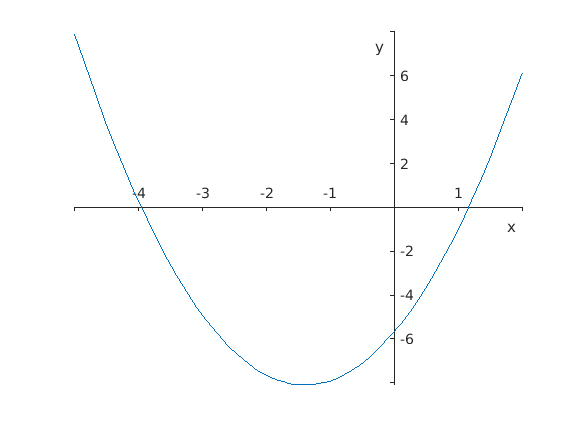


%plotting graph
fplot(y, [-5 2]) %stating desired x range

%centering origin
ax = gca;
ax.XAxisLocation='origin';
ax.YAxisLocation='origin';
%adding labels
xlabel("x")
ylabel("y")
box off %removing box outline


%declaring function to calculate discriminant
d = b^2-4*a*c

d =   39.993099104400002



%declaring function to calculate roots
r1 = (-1*b+sqrt(b^2-(4*a*c)))/2*a

r1 =    1.769883569650724


r2 = (-1*b-sqrt(b^2-(4*a*c)))/2*a

r2 =   -6.037485886450725


format long %this command adds more decimal places to responses

%edit values of a b and c as required
%a = 1
%b = 1
%c = 0
%commented out as these can carry over from above

%declaring function
sym eqn

$$ans = \mathrm{eqn}$$


%declaring quadratic
eqn = a*x^2+b*x+c;

%solving for roots of quadratic
sol = solve(eqn == 0, x);

%printing solutions
eval(sol)

ans =   -3.961245193876549
   1.161235473814341


%Logarythms
log(exp(2))

ans =      2


log(exp(3))

ans =      3


log(exp(4))

ans =      4



exp(log(2))

ans =      2


exp(log(3))

ans =    3.000000000000000


exp(log(4))

ans =      4


%Cup of tea equation
syms T(t)

%stating equation
T(t) = 21+68*exp(-.04*t)

$$T(t) = 68\,{\mathrm{e}}^{-\frac{t}{25}}+21$$


%calculating time taken to reach 58 C
time = solve(T == 58, t)

$$time = -25\,\log\left(\frac{37}{68}\right)$$


%printing time required to reach 58 C
eval(time)

ans = 15.2147


%%%Attempting to rearrange for small T however answer is given.
solve(T,t)

$$ans = -25\,\log\left(\frac{21}{68}\right)+25\,\pi \,\mathrm{i}$$


%this works however, not sure why above method does not
syms A B
solve(A == 21+68*exp(-.04*B) , B)

$$ans = -25\,\log\left(\frac{A}{68}-\frac{21}{68}\right)$$

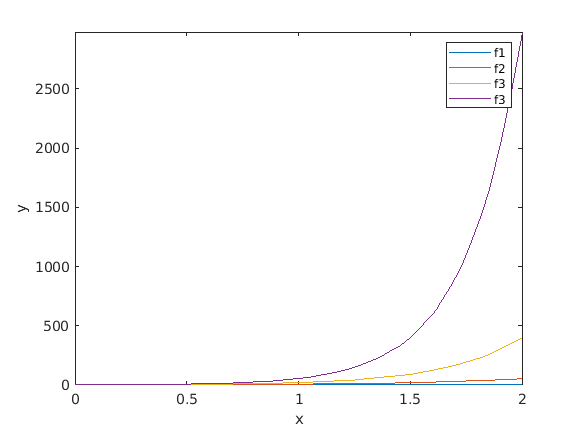

%Plotting exponential growth
syms f1(x) f2(x) f3(x) f4(x)

%declaring functions
f1(x) = exp(x);
f2(x) = exp(2*x);
f3(x) = exp(3*x);
f4(x) = exp(4*x);

fplot([f1, f2, f3, f4], [0 2]) %plotting

%adding labels
xlabel("x")
ylabel("y")

%adding legend
legend("f1", "f2","f3","f3") %adding in order they were plotted, I assume these match up

%centering graphs on origin
%not strictly necessary in this case as it was happening anyway, I am just
%getting in the habit of doing it
ax=gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";

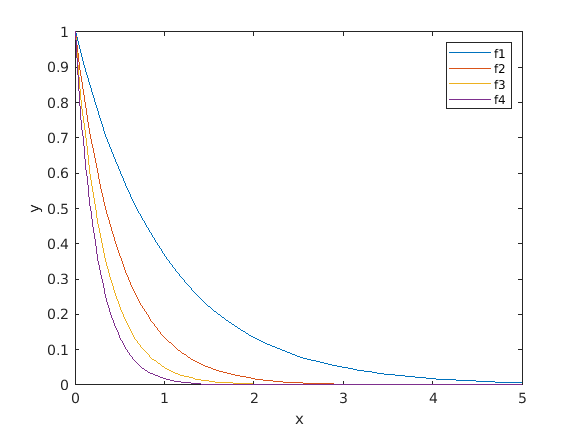

%plotting exponential decay
syms f1(x) f2(x) f3(x) f4(x)

%declaring functions
f1(x) = exp(-x);
f2(x) = exp(-2*x);
f3(x) = exp(-3*x);
f4(x) = exp(-4*x);

fplot([f1,f2,f3,f4], [0 5]) %plotting multiple graphs

%adding labels
xlabel("x")
ylabel("y")

legend("f1","f2","f3","f4")%adding legend

%centering graphs on origin
ax=gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";

%checking Logarythm answers (all should be true if i got my questions
%correct
isAlways(log(3)+log(6) == log(18))

ans = logical
   1



isAlways(log(24) == log(6)+log(4)) %error given here even though answer seems to be correct

ans = logical
   0


isAlways(log(24) == log(6*4)) %testing alternative method (which does work and should be equivalent)

ans = logical
   1



isAlways(log(exp(1)) == 1)

ans = logical
   1



isAlways(log(5^4) == 2*log(25))

ans = logical
   1



isAlways(log(2/16) == -1*log(8))

ans = logical
   1



isAlways(log(1) == 0)

ans = logical
   1
